[MATLAB | 情人节来绘制更立体的玫瑰花吧 (qq.com)](https://mp.weixin.qq.com/s/okJ27GaWiYCMOTHG2Bs3hA)

x=linspace(0,1,300);
theta=linspace(-2*pi,15*pi,300);
[x,theta]=meshgrid(x,theta);
phi=(pi/2).*exp(-theta./8./pi);
X=1-.5.*(1.25.*(1-mod(3.6.*theta,2*pi)./pi).^2-1/4).^2;
y=1.95653.*x.^2.*(1.27689.*x-1).^2.*sin(phi);
r=X.*(x.*sin(phi)+y.*cos(phi));
roseHdl=surf(r.*cos(theta),r.*sin(theta),X.*(x.*cos(phi)-y.*sin(phi)),'EdgeColor','none');


坐标区域修饰

在最后加入以下代码能让绘图更好看一些：

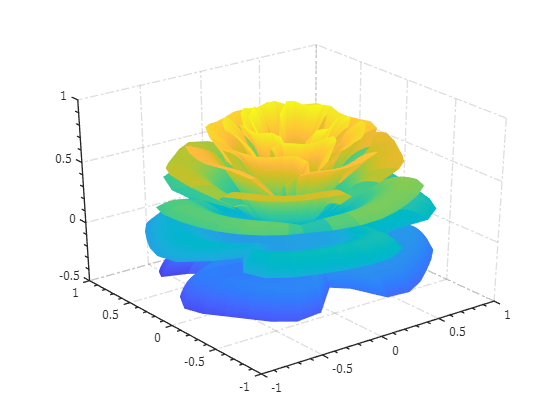


% 坐标区域修饰
ax=gca;hold on;grid on;
axis([-1,1,-1,1,-.5,1])
ax.FontName='Cambria';
ax.LineWidth=1;
ax.GridLineStyle='-.';
ax.Projection='perspective';
ax.XMinorTick='on';
ax.YMinorTick='on';
ax.ZMinorTick='on';

配色

可以调整颜色映射方向：

比如根据半径映射：

roseHdl.CData=r;

根据x轴坐标大小映射：


roseHdl.CData=r.*cos(theta);

配色可以自己弄点数值矩阵插值，比如：


roseHdl.CData=r;
CM=[0.5300    0.8300    0.8100
    0.5200    0.7500    0.8200
    0.4900    0.6200    0.8400
    0.4900    0.5600    0.8400
    0.4700    0.4900    0.8500
    0.4500    0.3500    0.8700
    0.9500    0.9500    0.9500];
CMX=linspace(0,1,size(CM,1));
CMXX=linspace(0,1,256)';
CM=[interp1(CMX,CM(:,1),CMXX,'pchip'),interp1(CMX,CM(:,2),CMXX,'pchip'),interp1(CMX,CM(:,3),CMXX,'pchip')];
colormap(CM)


随便举点例子：

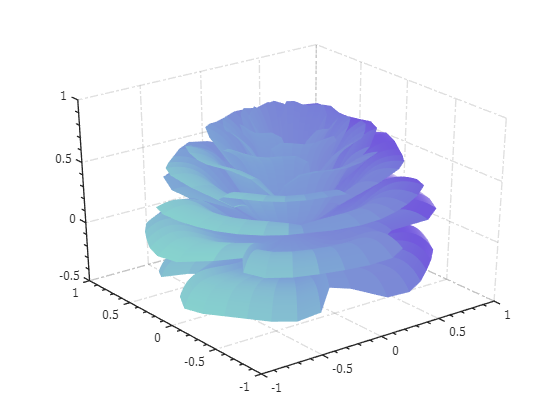


roseHdl.CData=r.*cos(theta);

% CM=slanCM('blues');

函数或变量 'slanCM' 无法识别。

% colormap(CM)
% clf;clc
% roseHdl.CData=r;
% CM=slanCM(134);
% colormap(CM)
% clf;clc
% roseHdl.CData=r;
% CM=slanCM(136);
% colormap(CM)

旋转

把代码改成这样就能一直旋转：


% 绘制玫瑰花
x=linspace(0,1,300);
theta=linspace(-2*pi,15*pi,300);
[x,theta]=meshgrid(x,theta);
phi=(pi/2).*exp(-theta./8./pi);
X=1-.5.*(1.25.*(1-mod(3.6.*theta,2*pi)./pi).^2-1/4).^2;
y=1.95653.*x.^2.*(1.27689.*x-1).^2.*sin(phi);
r=X.*(x.*sin(phi)+y.*cos(phi));
roseHdl=surf(r.*cos(theta),r.*sin(theta),X.*(x.*cos(phi)-y.*sin(phi)),'EdgeColor','none');

roseHdl.CData=r;
CM=slanCM('copper2');
CM=CM(1:180,:);
colormap(CM)


% 坐标区域修饰
ax=gca;hold on;grid on;
axis([-1,1,-1,1,-.5,1])
ax.FontName='Cambria';
ax.LineWidth=1;
ax.GridLineStyle='-.';
ax.Projection='perspective';
ax.XMinorTick='on';
ax.YMinorTick='on';
ax.ZMinorTick='on';
set(gcf,'Color',[1,1,1]);

% 循环绘图旋转起来
while true
    theta=theta+.01;
    roseHdl.XData=r.*cos(theta);
    roseHdl.YData=r.*sin(theta);
    pause(.01),drawnow
end


若想自动保存为gif，把最后部分旋转代码改为如下部分即可：


% 存储gif =================================================================
% R2022a及之后版本
n=0;
while true
    theta=theta+.01;
    roseHdl.XData=r.*cos(theta);
    roseHdl.YData=r.*sin(theta);
    if n<50
        exportgraphics(gcf,'test1.gif','Append',true)
    end
    n=n+1;
    pause(.01),drawnow
end

% R2022a之前版本
% n=0;DelayTime=.02;
% F=getframe(ax);
% [imind,cm]=rgb2ind(F.cdata,256);
% imwrite(imind,cm,'test2.gif','gif','Loopcount',inf,'DelayTime',DelayTime);
% while true
%     theta=theta+.01;
%     roseHdl.XData=r.*cos(theta);
%     roseHdl.YData=r.*sin(theta);
%     if n<50
%         F=getframe(ax);
%         [imind,cm]=rgb2ind(F.cdata,256);
%         imwrite(imind,cm,'test2.gif','gif','WriteMode','append','DelayTime',DelayTime);
%     end
%     n=n+1;
%     pause(.01),drawnow
% end